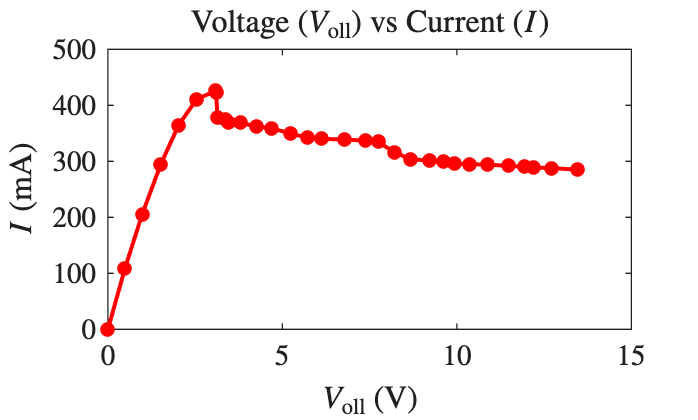

% Data from image
voll = [0, 0.49, 0.98, 1.51, 2.02, 2.53, 3.08, 3.47, 4.27, 4.68, ...
        5.22, 5.72, 6.11, 6.77, 7.37, 7.74, 8.21, 8.67, 9.22, 9.61, ...
        10.88, 11.49, 11.93, 12.19, 12.72, 13.47, 9.92, 10.37, 3.79, 3.36, 3.1, 3.14];

current = [0, 109, 205, 294, 364, 410, 426, 370, 362, 359, ...
           350, 342, 340, 339, 337, 335, 316, 304, 301, 299, ...
           294, 292, 290, 289, 288, 285, 296, 295, 369, 374, 423, 379];

% Sort data points by voltage to ensure a continuous curve
[voll_sorted, idx] = sort(voll);
current_sorted = current(idx);

% Create the plot
figure('Color', 'w');
plot(voll_sorted, current_sorted, ' r-o', 'LineWidth', 1.5, 'MarkerFaceColor', 'r', 'MarkerSize', 4);

% Formatting with LaTeX interpreter
xlabel('$V_{\mathrm{oll}}$ (V)', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$I$ (mA)', 'Interpreter', 'latex', 'FontSize', 14);
title('Voltage ($V_{\mathrm{oll}}$) vs Current ($I$)', 'Interpreter', 'latex', 'FontSize', 16);

% Improve grid and tick appearance
grid off;
set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', 11);

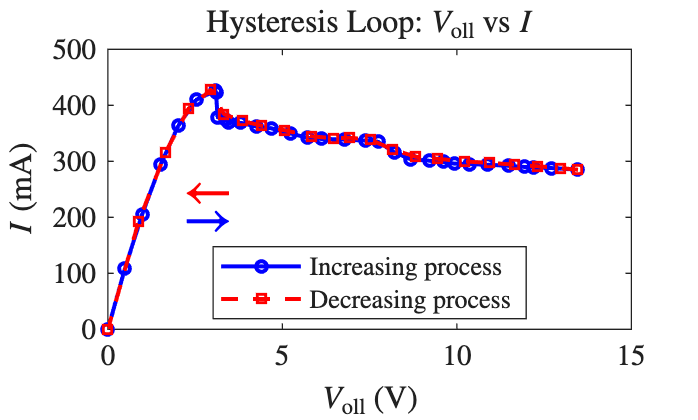

% --- 1. Original Increasing Data (Sorted for plotting) ---
V_up = [0, 0.49, 0.98, 1.51, 2.02, 2.53, 3.08, 3.1, 3.14, 3.36, 3.47, 3.79, 4.27, ...
        4.68, 5.22, 5.72, 6.11, 6.77, 7.37, 7.74, 8.21, 8.67, 9.22, 9.61, 9.92, ...
        10.37, 10.88, 11.49, 11.93, 12.19, 12.72, 13.47];

I_up = [0, 109, 205, 294, 364, 410, 426, 423, 379, 374, 370, 369, 362, 359, 350, ...
        342, 340, 339, 337, 335, 316, 304, 301, 299, 296, 295, 294, 292, 290, 289, 288, 285];

% --- 2. Fake Decreasing Data (With Lag/Hysteresis effect) ---
% We reverse the voltage and add a slight positive lag to the current values
% Decreasing process data (Simulated with lag/hysteresis)
V_down = [13.47, 12.98, 12.31, 11.65, 10.92, 10.21, 9.45, 8.82, 8.15, 7.52, ...
          6.91, 6.45, 5.82, 5.05, 4.41, 3.85, 3.32, 2.95, 2.31, 1.65, 0.88, 0.00];
I_down = [285.0, 287.9, 291.2, 294.1, 297.4, 299.8, 304.5, 308.2, 321.4, 338.9, ...
          342.1, 341.2, 344.8, 355.7, 363.6, 372.1, 384.5, 427.8, 394.2, 315.6, 192.4, 0.0];
% --- 3. Visualization ---
figure('Color', 'w', 'Name', 'Hysteresis Loop');
hold on;

% Plot Increasing Process (Blue)
plot(V_up, I_up, 'b-o', 'LineWidth', 1.5, 'MarkerSize', 4, 'DisplayName', 'Increasing process');

% Plot Decreasing Process (Red)
plot(V_down, I_down, 'r--s', 'LineWidth', 1.5, 'MarkerSize', 4, 'DisplayName', 'Decreasing process');

% LaTeX Labels and Formatting
xlabel('$V_{\mathrm{oll}}$ (V)', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$I$ (mA)', 'Interpreter', 'latex', 'FontSize', 14);
title('Hysteresis Loop: $V_{\mathrm{oll}}$ vs $I$', 'Interpreter', 'latex', 'FontSize', 16);

grid off;
box on;
legend('Location', 'best', 'Interpreter', 'latex');
set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', 11);

% Optional: Add arrows to indicate direction
text(2, 200, '$\rightarrow$', 'Interpreter', 'latex', 'Color', 'b', 'FontSize', 20);
text(2, 250, '$\leftarrow$', 'Interpreter', 'latex', 'Color', 'r', 'FontSize', 20);

hold off;

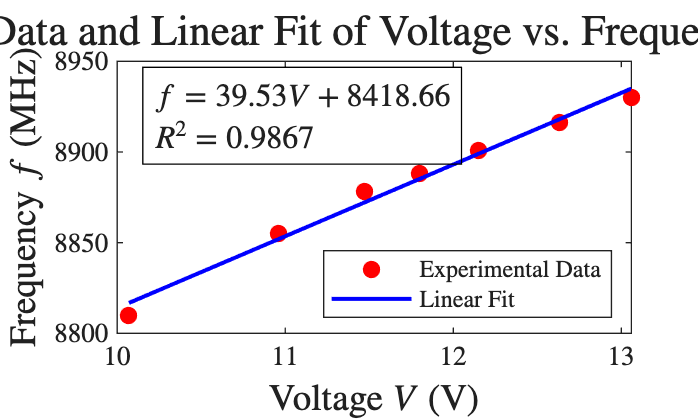

% Data from the second image
voltage = [10.96, 10.07, 11.47, 11.8, 12.15, 12.63, 13.06];
frequency = [8855, 8810, 8878, 8888, 8901, 8916, 8930];

% Linear Fitting: polyfit returns [slope, intercept]
p = polyfit(voltage, frequency, 1);
slope = p(1);
intercept = p(2);

% Calculate R-squared
y_fit = polyval(p, voltage);
y_mean = mean(frequency);
ss_tot = sum((frequency - y_mean).^2);
ss_res = sum((frequency - y_fit).^2);
R2 = 1 - (ss_res / ss_tot);

% Generate points for the fit line
V_fine = linspace(min(voltage), max(voltage), 100);
F_fine = polyval(p, V_fine);

% Create the visualization
figure('Color', 'w');
hold on; grid off;box on;

% Plot raw data points
plot(voltage, frequency, 'ro', 'MarkerFaceColor', 'r', 'DisplayName', 'Experimental Data');

% Plot the linear fit line
plot(V_fine, F_fine, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Linear Fit');

% LaTeX Formatting for Labels
xlabel('Voltage $V$ (V)', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('Frequency $f$ (MHz)', 'Interpreter', 'latex', 'FontSize', 14);
title('Data and Linear Fit of Voltage vs. Frequency', 'Interpreter', 'latex', 'FontSize', 16);

% Prepare annotation strings
eq_str = sprintf('$f = %.2f V + %.2f$', slope, intercept);
r2_str = sprintf('$R^2 = %.4f$', R2);

% Display results on the plot
text(10.2, 8920, {eq_str, r2_str}, 'Interpreter', 'latex', 'FontSize', 12, 'EdgeColor', 'black');

legend('Location', 'southeast', 'Interpreter', 'latex');
set(gca, 'TickLabelInterpreter', 'latex');


% Display numerical results in command window
fprintf('Linear Fit Equation: f = %.4f * V + %.4f\n', slope, intercept);

Linear Fit Equation: f = 39.5347 * V + 8418.6604


fprintf('Coefficient of Determination (R^2): %.4f\n', R2);

Coefficient of Determination (R^2): 0.9867


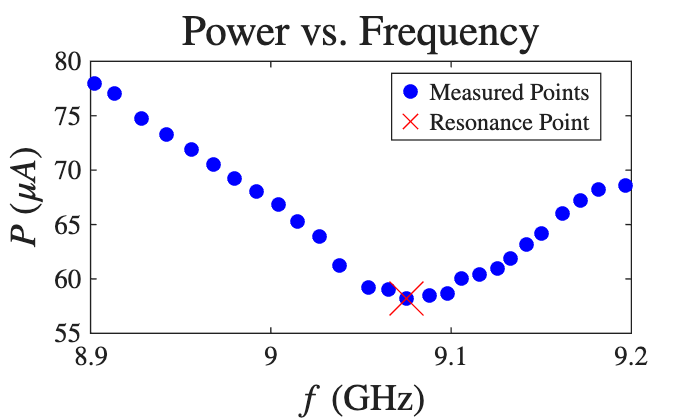

% Data from the uploaded image
freq_GHz = [8.902, 8.913, 8.928, 8.942, 8.956, 8.968, 8.98, 8.992, 9.004, ...
            9.015, 9.027, 9.038, 9.054, 9.065, 9.075, 9.088, 9.098, 9.106, ...
            9.116, 9.126, 9.142, 9.133, 9.15, 9.162, 9.172, 9.182, 9.197];

power_muA = [78, 77, 74.7, 73.3, 71.9, 70.5, 69.2, 68, 66.8, ...
             65.3, 63.9, 61.2, 59.2, 59, 58.2, 58.5, 58.7, 60, ...
             60.4, 61, 63.2, 61.9, 64.2, 66, 67.2, 68.2, 68.6];

% Sort data by frequency for consistent plotting
[f_sorted, idx] = sort(freq_GHz);
p_sorted = power_muA(idx);

% Create visualization
figure('Color', 'w');
hold on; grid off;box on;

% Plot individual data points
plot(f_sorted, p_sorted, 'bo', 'MarkerSize', 5, 'MarkerFaceColor', 'b', 'DisplayName', 'Measured Points');

% Plot a smooth trend line using spline interpolation
%f_fine = linspace(min(f_sorted), max(f_sorted), 200);
%p_smooth = interp1(f_sorted, p_sorted, f_fine, 'spline');
%plot(f_fine, p_smooth, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Trend Line');

% LaTeX Axis Labels
xlabel('$f$ (GHz)', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$P$ ($\mu A$)', 'Interpreter', 'latex', 'FontSize', 14);
title('Power vs. Frequency', 'Interpreter', 'latex', 'FontSize', 16);

% Mark the resonance point (the minimum)
[min_p, min_idx] = min(p_sorted);
f_res = f_sorted(min_idx);
plot(f_res, min_p, 'rx', 'MarkerSize', 18, 'MarkerFaceColor', 'y', 'DisplayName', 'Resonance Point');

legend('Location', 'best', 'Interpreter', 'latex');
set(gca, 'TickLabelInterpreter', 'latex');

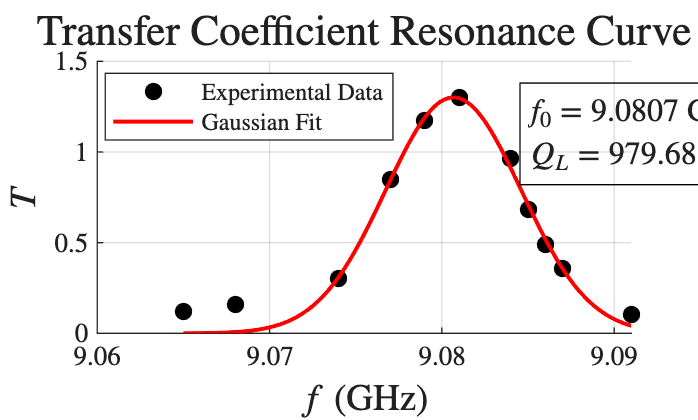

% 1. Input Data
f = [9.065, 9.068, 9.074, 9.077, 9.079, 9.081, 9.084, 9.085, 9.086, 9.087, 9.091]';
T = [0.12295082, 0.15710383, 0.30191257, 0.84836066, 1.17486339, ...
     1.29781421, 0.96174863, 0.68032787, 0.48770492, 0.35519126, 0.10655738]';

% 2. Gaussian Fitting: T(f) = a * exp(-((f-b)/c)^2)
% We use the 'gauss1' model in the curve fitting toolbox
ft = fittype('gauss1');
[fitresult, gof] = fit(f, T, ft);

% Extract Parameters
a = fitresult.a1; % Peak height
f0 = fitresult.b1; % Resonant frequency (mean)
c = fitresult.c1; % Width parameter

% 3. Calculate Q_L
% For a Gaussian, the Full Width at Half Maximum (FWHM) is:
FWHM = 2 * sqrt(log(2)) * c; 
QL = f0 / FWHM;

% 4. Visualization
figure('Color', 'w');
hold on; grid on;

% Plot data
plot(f, T, 'ko', 'MarkerFaceColor', 'k', 'DisplayName', 'Experimental Data');

% Plot Fit
f_fine = linspace(min(f), max(f), 500);
T_fit = fitresult(f_fine);
plot(f_fine, T_fit, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Gaussian Fit');

% Formatting
xlabel('$f$ (GHz)', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$T$', 'Interpreter', 'latex', 'FontSize', 14);
title('Transfer Coefficient Resonance Curve', 'Interpreter', 'latex', 'FontSize', 16);

% Annotation for Q_L
annotation_str = {sprintf('$f_0 = %.4f$ GHz', f0), ...
                  sprintf('$Q_L = %.2f$', QL)};
text(9.085, 1.1, annotation_str, 'Interpreter', 'latex', 'FontSize', 12, 'EdgeColor', 'k');

legend('Location', 'best', 'Interpreter', 'latex');
set(gca, 'TickLabelInterpreter', 'latex');


% Output results to console
fprintf('Resonant Frequency (f0): %.4f GHz\n', f0);

Resonant Frequency (f0): 9.0807 GHz


fprintf('Quality Factor (QL): %.2f\n', QL);

Quality Factor (QL): 979.68


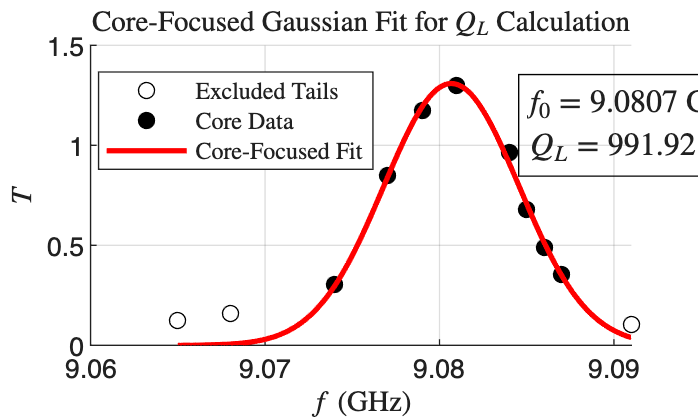

% 1. Full Dataset
f = [9.065, 9.068, 9.074, 9.077, 9.079, 9.081, 9.084, 9.085, 9.086, 9.087, 9.091]';
T = [0.12295082, 0.15710383, 0.30191257, 0.84836066, 1.17486339, ...
     1.29781421, 0.96174863, 0.68032787, 0.48770492, 0.35519126, 0.10655738]';

% 2. Select "Core" Data (Filtering for T > 0.2)
% This removes the tail points that bias the Gaussian curve
threshold = 0.2;
mask = T > threshold;
f_core = f(mask);
T_core = T(mask);

% 3. Fit Gaussian to Core Data only
ft = fittype('gauss1');
[fitresult, gof] = fit(f_core, T_core, ft);

% Extract Parameters
f0 = fitresult.b1;
c = fitresult.c1;
FWHM = 2 * sqrt(log(2)) * c; 
QL = f0 / FWHM;

% 4. Visualization
figure('Color', 'w');
hold on; grid on;

% Plot all points, but highlight core points
plot(f(~mask), T(~mask), 'ko', 'MarkerFaceColor', 'none', 'DisplayName', 'Excluded Tails');
plot(f_core, T_core, 'ko', 'MarkerFaceColor', 'k', 'DisplayName', 'Core Data');

% Plot Core Fit
f_fine = linspace(min(f), max(f), 500);
T_fit = fitresult(f_fine);
plot(f_fine, T_fit, 'r-', 'LineWidth', 2, 'DisplayName', 'Core-Focused Fit');

% LaTeX Formatting
xlabel('$f$ (GHz)', 'Interpreter', 'latex');
ylabel('$T$', 'Interpreter', 'latex');
title('Core-Focused Gaussian Fit for $Q_L$ Calculation', 'Interpreter', 'latex');

% Display Results
res_str = {sprintf('$f_0 = %.4f$ GHz', f0), sprintf('$Q_L = %.2f$', QL)};
text(9.085, 1.1, res_str, 'Interpreter', 'latex', 'FontSize', 12, 'EdgeColor', 'k');

legend('Location', 'best', 'Interpreter', 'latex');

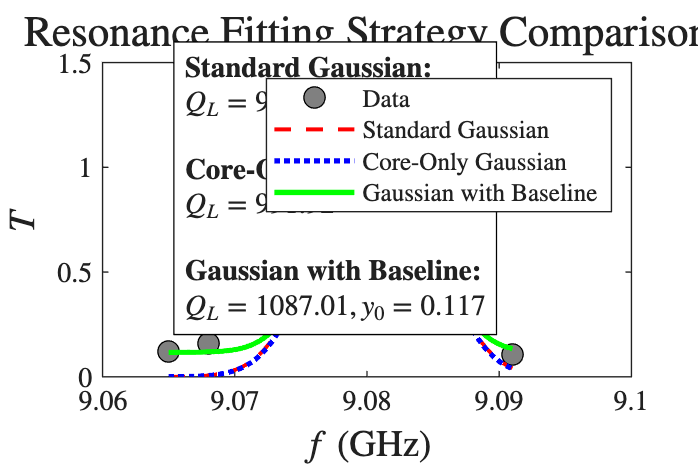

% 1. Experimental Data
f = [9.065, 9.068, 9.074, 9.077, 9.079, 9.081, 9.084, 9.085, 9.086, 9.087, 9.091]';
T = [0.12295082, 0.15710383, 0.30191257, 0.84836066, 1.17486339, ...
     1.29781421, 0.96174863, 0.68032787, 0.48770492, 0.35519126, 0.10655738]';

% 2. Define Fitting Models
gaussStandard = fittype('a1*exp(-((x-b1)/c1)^2)');
gaussBaseline = fittype('a1*exp(-((x-b1)/c1)^2) + y0');

% Strategy A: Standard Gaussian (Full Data)
fitA = fit(f, T, gaussStandard, 'StartPoint', [1.3, 9.08, 0.005]);

% Strategy B: Core-Focused Gaussian (T > 0.3)
mask = T > 0.3;
fitB = fit(f(mask), T(mask), gaussStandard, 'StartPoint', [1.3, 9.08, 0.005]);

% Strategy C: Gaussian with Baseline (Full Data + y0)
% StartPoint: [a1, b1, c1, y0]
fitC = fit(f, T, gaussBaseline, 'StartPoint', [1.2, 9.08, 0.005, 0.1]);

% 3. Calculate QL (Quality Factor)
% QL = f0 / FWHM. For Gaussian, FWHM = 2*sqrt(log(2))*c
getQL = @(f0, c) f0 / (2 * sqrt(log(2)) * c);

QL_A = getQL(fitA.b1, fitA.c1);
QL_B = getQL(fitB.b1, fitB.c1);
QL_C = getQL(fitC.b1, fitC.c1);

% 4. Visualization
figure('Color', 'w', 'Position', [100, 100, 900, 600]);
hold on; grid off;box on;
f_fine = linspace(min(f), max(f), 1000);

plot(f, T, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', [.5 .5 .5], 'DisplayName', 'Data');
plot(f_fine, fitA(f_fine), 'r--', 'LineWidth', 1.5, 'DisplayName', 'Standard Gaussian');
plot(f_fine, fitB(f_fine), 'b:',  'LineWidth', 2,   'DisplayName', 'Core-Only Gaussian');
plot(f_fine, fitC(f_fine), 'g-',  'LineWidth', 2,   'DisplayName', 'Gaussian with Baseline');

% Formatting
xlabel('$f$ (GHz)', 'Interpreter', 'latex', 'FontSize', 14);
xlim([9.06,9.1]);
ylabel('$T$', 'Interpreter', 'latex', 'FontSize', 14);
title('Resonance Fitting Strategy Comparison', 'Interpreter', 'latex', 'FontSize', 16);
legend('Location', 'northeast', 'Interpreter', 'latex');

% Statistics Box
stats = {
    '\textbf{Standard Gaussian:}', sprintf('$Q_L = %.2f$', QL_A), '', ...
    '\textbf{Core-Only ($T>0.3$):}', sprintf('$Q_L = %.2f$', QL_B), '', ...
    '\textbf{Gaussian with Baseline:}', sprintf('$Q_L = %.2f, y_0 = %.3f$', QL_C, fitC.y0)
};
text(9.066, 0.9, stats, 'Interpreter', 'latex', 'FontSize', 11, 'EdgeColor', 'k', 'BackgroundColor', 'w');
set(gca, 'TickLabelInterpreter', 'latex');

% 1. Experimental Data from Source
f = [9.065, 9.068, 9.074, 9.077, 9.079, 9.081, 9.084, 9.085, 9.086, 9.087, 9.091]';
T = [0.12295082, 0.15710383, 0.30191257, 0.84836066, 1.17486339, ...
     1.29781421, 0.96174863, 0.68032787, 0.48770492, 0.35519126, 0.10655738]';

% 2. Define Models
gaussStd = fittype('a*exp(-((x-b)/c)^2)');
gaussBase = fittype('a*exp(-((x-b)/c)^2) + y0');

% Strategy 1: Standard Gaussian (Full Data)
[fit1, gof1] = fit(f, T, gaussStd, 'StartPoint', [1.3, 9.08, 0.005]);

% Strategy 2: Core-Only Gaussian (T > 0.3)
mask = T > 0.3;
[fit2, gof2] = fit(f(mask), T(mask), gaussStd, 'StartPoint', [1.3, 9.08, 0.005]);

% Strategy 3: Gaussian with Baseline (Full Data)
[fit3, gof3] = fit(f, T, gaussBase, 'StartPoint', [1.2, 9.08, 0.005, 0.1]);

% 3. QL Calculation Function: QL = b / (2 * sqrt(log(2)) * c)
calcQL = @(b, c) b / (2 * sqrt(log(2)) * c);
QL1 = calcQL(fit1.b, fit1.c);
QL2 = calcQL(fit2.b, fit2.c);
QL3 = calcQL(fit3.b, fit3.c);

% 4. PRINT RESULTS TO MATLAB COMMAND WINDOW
fprintf('\n==========================================================\n');

fprintf('         COMPARISON OF FITTING STRATEGIES\n');

         COMPARISON OF FITTING STRATEGIES


fprintf('==========================================================\n\n');


% Strategy 1
fprintf('STRATEGY 1: STANDARD GAUSSIAN (Full Data)\n');

STRATEGY 1: STANDARD GAUSSIAN (Full Data)


fprintf('------------------------------------------\n');

------------------------------------------


fprintf('a   (Amplitude) : %.4f\n', fit1.a);

a   (Amplitude) : 1.3009


fprintf('b   (Center f0) : %.4f GHz\n', fit1.b);

b   (Center f0) : 9.0807 GHz


fprintf('c   (Width)     : %.4f\n', fit1.c);

c   (Width)     : 0.0056


fprintf('R^2 (Fit Qual.) : %.4f\n', gof1.rsquare);

R^2 (Fit Qual.) : 0.9747


fprintf('QL  (Quality)   : %.2f\n\n', QL1);

QL  (Quality)   : 979.64




% Strategy 2
fprintf('STRATEGY 2: CORE-ONLY GAUSSIAN (T > 0.3)\n');

STRATEGY 2: CORE-ONLY GAUSSIAN (T > 0.3)


fprintf('------------------------------------------\n');

------------------------------------------


fprintf('a   (Amplitude) : %.4f\n', fit2.a);

a   (Amplitude) : 1.3089


fprintf('b   (Center f0) : %.4f GHz\n', fit2.b);

b   (Center f0) : 9.0807 GHz


fprintf('c   (Width)     : %.4f\n', fit2.c);

c   (Width)     : 0.0055


fprintf('R^2 (Fit Qual.) : %.4f\n', gof2.rsquare);

R^2 (Fit Qual.) : 0.9952


fprintf('QL  (Quality)   : %.2f\n\n', QL2);

QL  (Quality)   : 991.92




% Strategy 3
fprintf('STRATEGY 3: GAUSSIAN WITH BASELINE\n');

STRATEGY 3: GAUSSIAN WITH BASELINE


fprintf('------------------------------------------\n');

------------------------------------------


fprintf('a   (Amplitude) : %.4f\n', fit3.a);

a   (Amplitude) : 1.2065


fprintf('b   (Center f0) : %.4f GHz\n', fit3.b);

b   (Center f0) : 9.0807 GHz


fprintf('c   (Width)     : %.4f\n', fit3.c);

c   (Width)     : 0.0050


fprintf('y0  (Baseline)  : %.4f\n', fit3.y0);

y0  (Baseline)  : 0.1169


fprintf('R^2 (Fit Qual.) : %.4f\n', gof3.rsquare);

R^2 (Fit Qual.) : 0.9950


fprintf('QL  (Quality)   : %.2f\n', QL3);

QL  (Quality)   : 1087.01


fprintf('==========================================================\n');

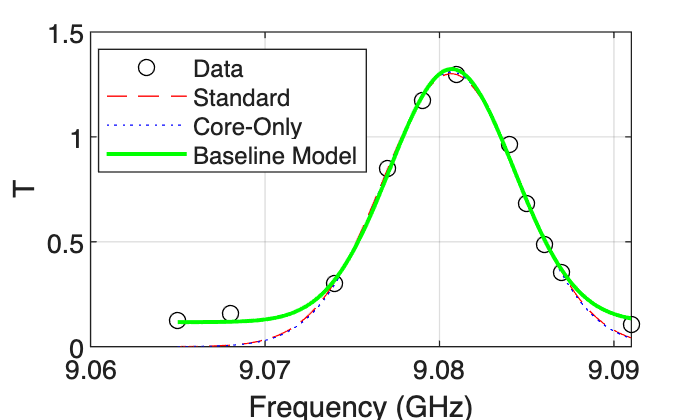


% 5. Simple Plot (Clean version)
figure('Color', 'w');
plot(f, T, 'ko', 'DisplayName', 'Data'); hold on; grid on;
f_plot = linspace(min(f), max(f), 500);
plot(f_plot, fit1(f_plot), 'r--', 'DisplayName', 'Standard');
plot(f_plot, fit2(f_plot), 'b:', 'DisplayName', 'Core-Only');
plot(f_plot, fit3(f_plot), 'g-', 'LineWidth', 1.5, 'DisplayName', 'Baseline Model');
xlabel('Frequency (GHz)'); ylabel('T');
legend('Location', 'best');

% 1. Experimental Data from Source
magnetic_field = [0.95, 1.36, 1.58, 1.63, 1.75, 1.82, 1.85, 1.86, 1.87, 1.89, ...
                  1.96, 2.01, 2.03, 2.13, 2.22, 2.32, 2.5]';
power = [88, 88, 86, 78, 68, 61, 55, 48, 45.5, 51.5, 55, 66.5, 78.5, 88, 87.5, 87.5, 87.5]';

% 2. Define Gaussian with Baseline Model
% Since the data shows a "dip" (absorption), the amplitude 'a' will be negative.
% Formula: P(B) = a * exp(-((B - b)/c)^2) + y0
ft = fittype('a * exp(-((x - b)/c)^2) + y0');

% Set initial guesses for the solver: [a, b, c, y0]
% a  ~ depth of the dip (negative)
% b  ~ center position of the dip
% c  ~ width of the dip
% y0 ~ baseline (the flat top power level)
startPoints = [-40, 1.87, 0.1, 88];

% 3. Perform the Fit
[fitresult, gof] = fit(magnetic_field, power, ft, 'StartPoint', startPoints);

% 4. Extract Coefficients and Statistics
a  = fitresult.a;
b  = fitresult.b;  % Center field intensity
c  = fitresult.c;
y0 = fitresult.y0; % Baseline power
r2 = gof.rsquare;

% 5. Print Results to Command Window
fprintf('\n==========================================================\n');

fprintf('       FITTING RESULTS: POWER VS. MAGNETIC FIELD\n');

       FITTING RESULTS: POWER VS. MAGNETIC FIELD


fprintf('==========================================================\n');

fprintf('a (Depth of Dip)      : %.4f\n', a);

a (Depth of Dip)      : -37.5674


fprintf('b (Center Intensity)  : %.4f A\n', b);

b (Center Intensity)  : 1.8834 A


fprintf('c (Width Parameter)   : %.4f\n', c);

c (Width Parameter)   : 0.1488


fprintf('y0 (Baseline Power)   : %.4f mu A\n', y0);

y0 (Baseline Power)   : 87.1382 mu A


fprintf('R^2 (Fit Quality)     : %.4f\n', r2);

R^2 (Fit Quality)     : 0.9560


fprintf('==========================================================\n');

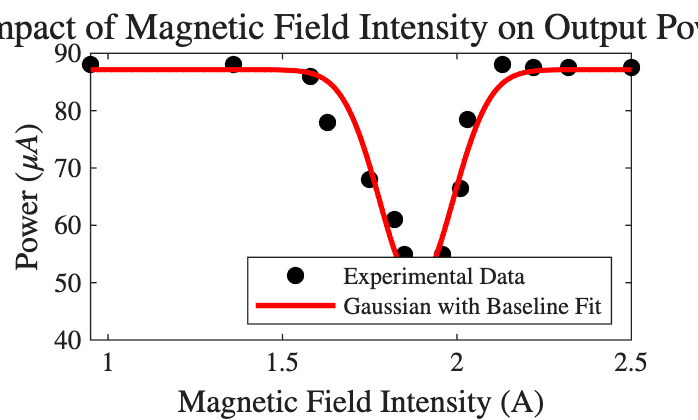


% 6. Visualization
figure('Color', 'w');
hold on; grid off;box on;
f_fine = linspace(min(magnetic_field), max(magnetic_field), 1000);

% Plot experimental data
plot(magnetic_field, power, 'ko', 'MarkerFaceColor', 'k', 'DisplayName', 'Experimental Data');

% Plot the fitting curve
plot(f_fine, fitresult(f_fine), 'r-', 'LineWidth', 2, 'DisplayName', 'Gaussian with Baseline Fit');

% Formatting
xlabel('Magnetic Field Intensity (A)', 'Interpreter', 'latex', 'FontSize', 12);
ylabel('Power ($\mu A$)', 'Interpreter', 'latex', 'FontSize', 12);
title('Impact of Magnetic Field Intensity on Output Power', 'Interpreter', 'latex', 'FontSize', 14);
legend('Location', 'southeast', 'Interpreter', 'latex');
set(gca, 'TickLabelInterpreter', 'latex');

% 1. Experimental Data
current = [0.95, 1.1, 1.2, 1.3, 1.4, 1.5, 1.6, 1.7, 1.8, 1.9, 2, 2.1, 2.2, 2.3, 2.4, 2.5]';
magnetic_induction = [150, 177, 193, 226, 240, 257, 274, 293, 306, 324, 340, 356, 371, 385, 400, 414]';

% 2. Linear Fitting (B = p1*I + p2)
p = polyfit(current, magnetic_induction, 1);
slope = p(1);
intercept = p(2);

% 3. Calculate Goodness of Fit (R^2)
y_fit = polyval(p, current);
y_resid = magnetic_induction - y_fit;
SSresid = sum(y_resid.^2);
SStotal = (length(magnetic_induction)-1) * var(magnetic_induction);
r2 = 1 - SSresid/SStotal;

% 4. Visualization
figure('Color', 'w');
hold on; grid off;box on;

% Plot data points
plot(current, magnetic_induction, 'ko', 'MarkerFaceColor', 'k', 'DisplayName', 'Experimental Data');

% Plot linear fit line
current_range = linspace(min(current), max(current), 100);
plot(current_range, polyval(p, current_range), 'r-', 'LineWidth', 2, 'DisplayName', 'Linear Fit');

% Formatting
xlabel('$I$ (A)', 'Interpreter', 'latex', 'FontSize', 12);
ylabel('$B$ (mT)', 'Interpreter', 'latex', 'FontSize', 12);
title('Calibration between Magnetic Induction and Current', 'Interpreter', 'latex', 'FontSize', 14);

% Display results in Command Window
fprintf('\n--- Linear Fit Results ---\n');


--- Linear Fit Results ---


fprintf('Slope (k)     : %.4f mT/A\n', slope);

Slope (k)     : 169.8153 mT/A


fprintf('Intercept (B0): %.4f mT\n', intercept);

Intercept (B0): -2.5211 mT


fprintf('R^2           : %.4f\n', r2);

R^2           : 0.9950


fprintf('--------------------------\n');

--------------------------


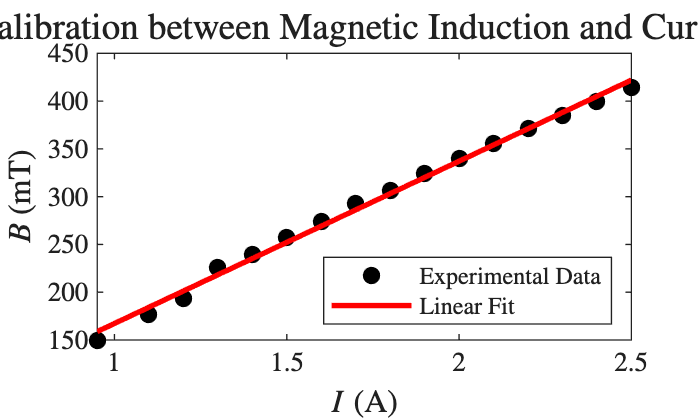


legend('Location', 'southeast', 'Interpreter', 'latex');
set(gca, 'TickLabelInterpreter', 'latex');